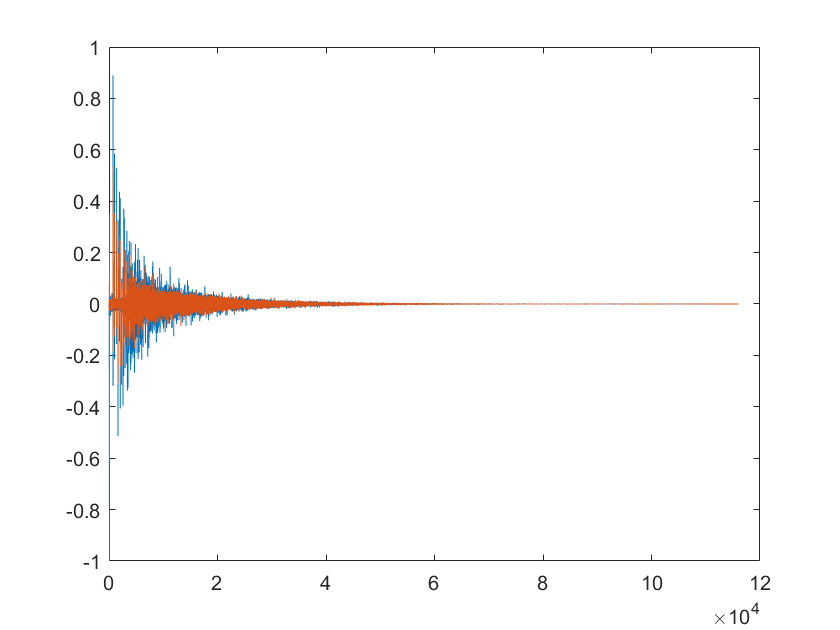


[s1, fs1] = audioread('hall.wav');% Use wavread function
[s2, fs2] = audioread('man.wav'); % Use wavread function   
% Sampling rate adjustment 
fs = lcm(fs1, fs2); 
if fs > fs1 
    fs_fac1 = floor(fs / fs1); 
    s1_fs = zeros(1, fs_fac1*numel(s1));     
    s1_fs(1:fs_fac1:end) = s1;
    else 
    s1_fs = s1;
end 

if fs > fs2 
    fs_fac2 = floor(fs / fs2); 
    s2_fs = zeros(1, fs_fac2*length(s2));    
    s2_fs(1:fs_fac2:end) = s2; 
    else 
    s2_fs = s2; 
end 
  
% Length adjustment 
L1 = length(s1_fs); L2 = length(s2_fs);
if L1 > L2 
    s2_fs = [s2_fs zeros(1, L1 - L2)]; 
else 
    s1_fs = [s1_fs zeros(1, L2 - L1)]; 
end 
  
%Mixing of signals        
s_m = s1_fs + s2_fs; 
fs=fs1+fs2;
  
%Play back of sounds 
sound(s1,fs1) %Play sound of signal 1 (s1 & fs1) – use sound function input('Press ...'); 
plot(s1)

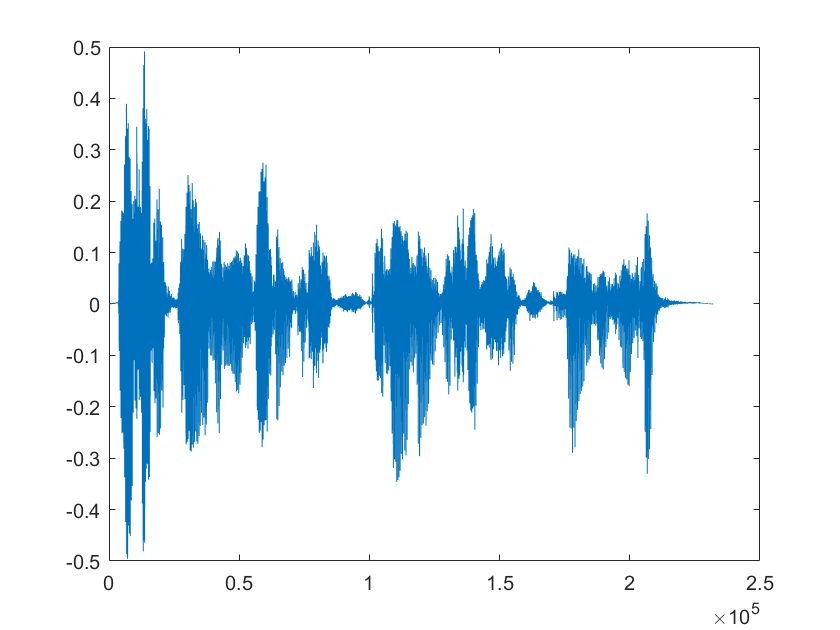

sound(s2,fs2) %Play sound of signal 2 (s2 & fs2) – use sound function input('Press ...'); 
plot(s2)

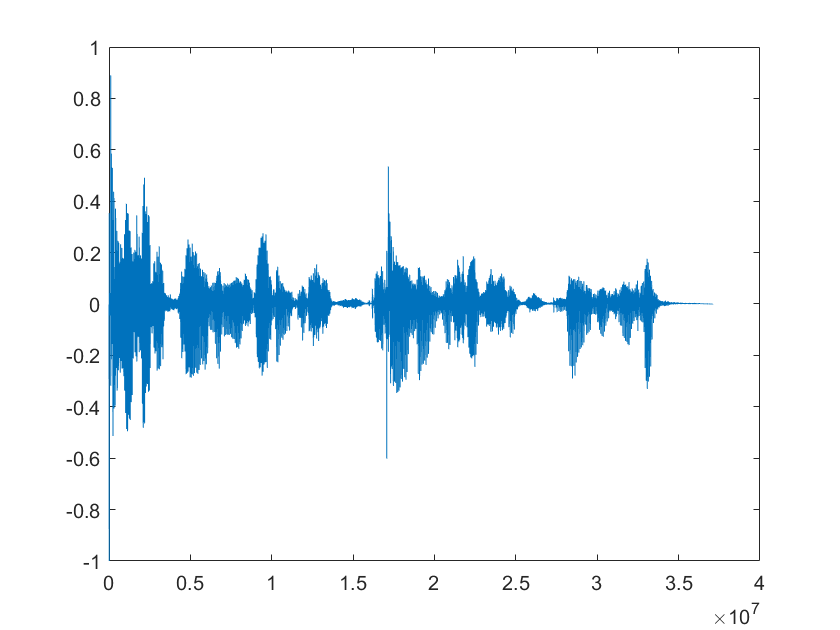

sound(s_m,fs); %Play sound of mixed signal (s_m & fs) – use sound function
plot(s_m)